# Open Loop Control

JJRATH- Feb2021 Open Loop Control performance on Systems

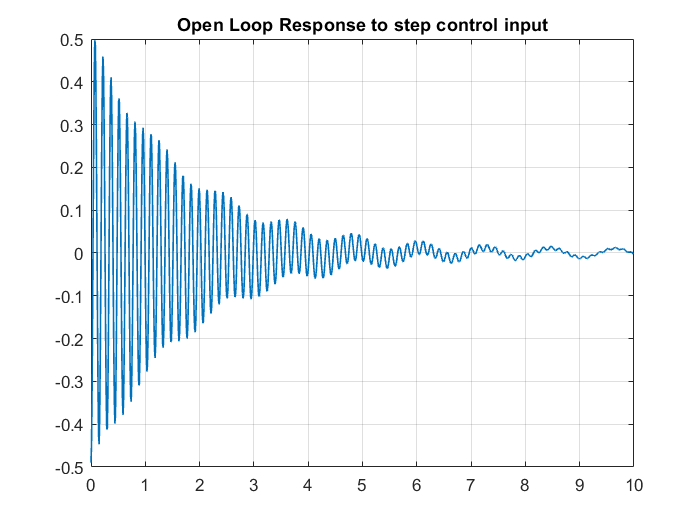

%--------------------------
%----------------------------
% Ex1: Active Suspension System
% qcar_CT = SISO_Nom_Suspension; % The nominal suspension model
qcar_CT = SISO_Dis_suspension; % The disturbed suspension model
t = 0:.01:10-0.01;
%-- Design Requirements
% A suspension system should have satisfactory road holding ability, 
% while still providing comfort when riding over bumps and holes in the road.
% When the vehicle is experiencing any road disturbance (i.e. pot holes, cracks, and uneven pavement),
% the vehicle body should not have large oscillations, and the oscillations 
% should dissipate quickly. Let us consider the suspension deflection as the output for this probelm.
% The road disturbance (W) in this problem will be simulated by a step input.
% This step could represent the vehicle coming out of a pothole. 
% We want to design a controller so that the output (xb-xw) has an overshoot less than 5
% and a settling time shorter than 5 seconds.
% For example, when the bus runs onto a 10-cm step, the bus body will oscillate within a range of +/- 5 mm and
% return to a smooth ride within 5 seconds.

%---- STEP 1: Getting the TF of the inputs w.r.t output
[NUM1,DEN1] = ss2tf(qcar_CT.a,qcar_CT.b,qcar_CT.c,qcar_CT.d,1); % TF respect to input 1 i.e. fs
[NUM2,DEN2] = ss2tf(qcar_CT.a,qcar_CT.b,qcar_CT.c,qcar_CT.d,2); % TF respect to input 2 i.e. road disturbance
H1_11 = tf(NUM1,DEN1); % TF of output 1 and input 1
H1_12 = tf(NUM2,DEN2); % TF of output 1 and input 2

%-- STEP 2: Open Loop Controller of System to Nominal Input 
%- Let us say we are providing a step input to the system as the force fs
%i.e. u1 (Note we cannnot control u2 as its road disturbance)

%---System response of SS considering u1 = non zero, but  u2 = 0 (i.e. no road disturabance)
u_f = 0.1*ones(1,length(t)); % % Step input
x0_f = [0.01 0.1 0.5 .1]; % Initial conditions are  non- zero.
%--- Simulate 
[Yo_n,t,Xo_n] = lsim(qcar_CT,[u_f ;u_f*0],t,x0_f); % We want ouput, state information
%-- Plot the response
figure; 
plot(t,Yo_n,'LineWidth',1); grid on; title('Open Loop Response to step control input')

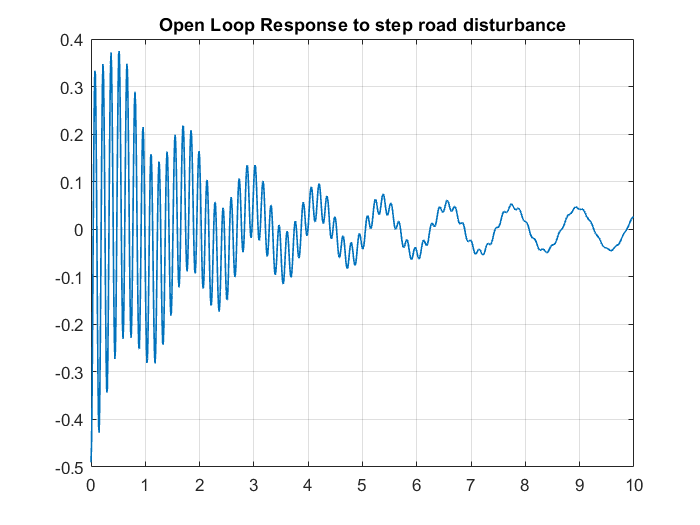


%--- System response of SS considering u2 = road disturbance, but  u1 = 0
u_road = 0.1*ones(1,length(t)); % % Random road disturbance i.e. a step of magnitude 0.1
x0_f = [0.01 0.1 0.5 .1]; % Initial conditions are  non- zero.
%--- Simulate 
[Yo_d,t,Xo_d] = lsim(qcar_CT,[u_road*0 ;u_road],t,x0_f); % We want ouput, state information
%-- Plot the response
figure; 
plot(t,Yo_d,'LineWidth',1); grid on; title('Open Loop Response to step road disturbance')

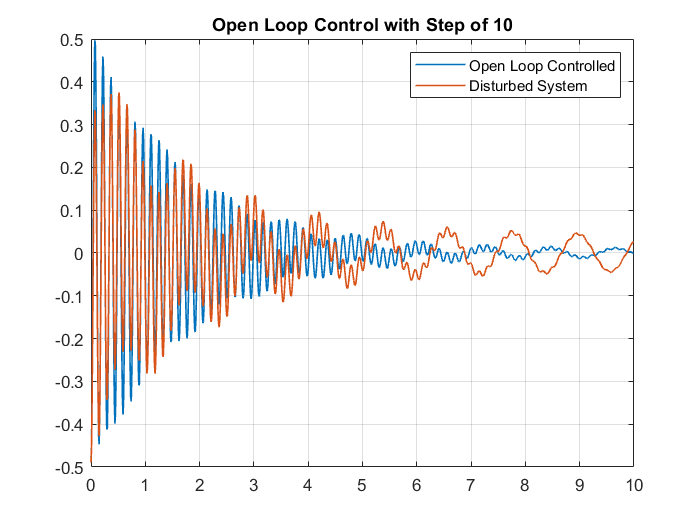



%-- Lets try changing our u1 and see if effect of u2 reduces (i.e. provide
%open loop contorl for system)

u_f1 = 10*ones(1,length(t)); % % Open Loop Step Control 
u_f2 = 100*ones(1,length(t)); % % Open Loop Step Control 
u_f3 = -10*ones(1,length(t)); % Open Loop Step Control 
u_f4 = 10*rand(1,length(t)); % % 
%--- Simulate 
[Yoc_d1,t,Xoc_d1] = lsim(qcar_CT,[u_f1 ;u_f1*0],t,x0_f); % We want ouput, state information
[Yoc_d2,t,Xoc_d2] = lsim(qcar_CT,[u_f2 ;u_f2*0],t,x0_f); % We want ouput, state information
[Yoc_d3,t,Xoc_d3] = lsim(qcar_CT,[u_f3 ;u_f3*0],t,x0_f); % We want ouput, state information
[Yoc_d4,t,Xoc_d4] = lsim(qcar_CT,[u_f4 ;u_f4*0],t,x0_f); % We want ouput, state information

%-- Plot the response
figure; 
plot(t,Yoc_d1,'LineWidth',1); hold on; plot(t,Yo_d,'LineWidth',1); grid on;
legend('Open Loop Controlled','Disturbed System'); title('Open Loop Control with Step of 10');

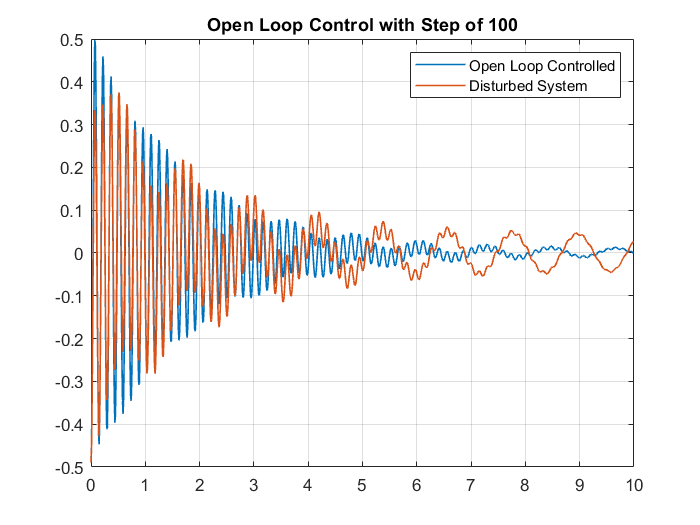


figure; 
plot(t,Yoc_d2,'LineWidth',1); hold on; plot(t,Yo_d,'LineWidth',1); grid on;
legend('Open Loop Controlled','Disturbed System'); title('Open Loop Control with Step of 100');

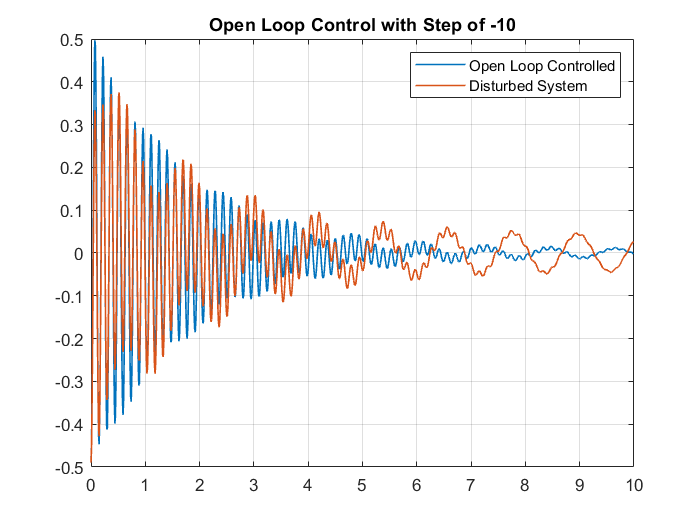


figure; 
plot(t,Yoc_d3,'LineWidth',1); hold on; plot(t,Yo_d,'LineWidth',1); grid on;
legend('Open Loop Controlled','Disturbed System'); title('Open Loop Control with Step of -10');

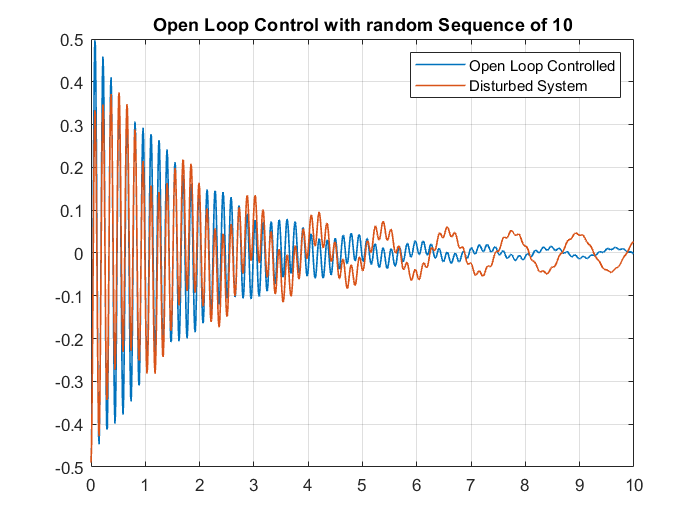


figure; 
plot(t,Yoc_d4,'LineWidth',1); hold on; plot(t,Yo_d,'LineWidth',1); grid on;
legend('Open Loop Controlled','Disturbed System'); title('Open Loop Control with random Sequence of 10');